e=[1 0 0];
Q1 = transpose(axang2quat(vrrotvec([0 -1 -30/2],e)))

Q1 =     0.7071
         0
   -0.7055
    0.0470


Q2 = transpose(axang2quat(vrrotvec([0 0 1],e)))

Q2 =     0.7071
         0
    0.7071
         0


W1 = deg2rad([0.8 -0.6 0])'

W1 =     0.0140
   -0.0105
         0


W2 = deg2rad([0 0 0])'

W2 =      0
     0
     0



maxW1= norm(W1)

maxW1 = 0.0175

maxW2=deg2rad(1)

maxW2 = 0.0175

maxW2= maxW1

maxW2 = 0.0175

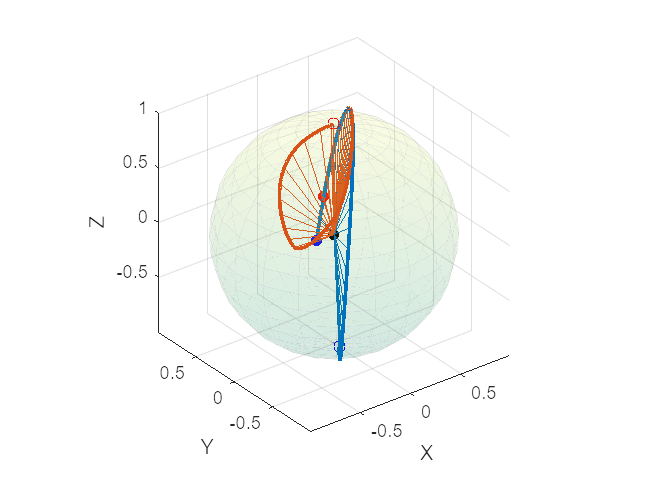


d=100;
tSim=300;
t=[0];
dt=0.1;
q=[q0];
w=[omega0];
u=[0;0;0];
while t(end) < tSim
    t(end+1) = t(end)+dt;

    % Ограничение скорости
    %W1(:,end) = trimVector(W1(:,end) ,maxW1);
    W2(:,end) = trimVector(W2(:,end) ,maxW2);

    [q1,w1] = rotationTick( Q1(:,end), Q1(:,end), W1(:,end), 0,0.1, J, dt);
    [q2,w2] = rotationTick( Q2(:,end), Q1(:,end), W2(:,end), 2,0.1, J, dt);
    Q1=[Q1 q1];
    Q2=[Q2 q2];
    W1=[W1 w1];
    W2=[W2 w2];
end

R1=[];
R2=[];

for i=1:size(Q1,2)
    R1=[R1; quatrotate(Q1(:,i)',e)];
    R2=[R2; quatrotate(Q2(:,i)',e*1.01)];
end

X1=R1(:,1);
Y1=R1(:,2);
Z1=R1(:,3);
X2=R2(:,1);
Y2=R2(:,2);
Z2=R2(:,3);

figure
lw=2;
plot3(X1,Y1,Z1,'LineWidth',lw);
hold on
plot3(X2,Y2,Z2,'LineWidth',lw);
scatter3(0,0,0,"filled","black");
scatter3(X1(1),Y1(1),Z1(1),"blue");
scatter3(X2(1),Y2(1),Z2(1),"red");
scatter3(X1(end),Y1(end),Z1(end),"filled","blue");
scatter3(X2(end),Y2(end),Z2(end),"filled","red");

[Xe,Ye,Ze]=sphere();
Re=0.99;
Xe=Xe*Re;
Ye=Ye*Re;
Ze=Ze*Re;
s=surf(Xe,Ye,Ze);
colormap("summer")

alpha=0.1;
s.FaceAlpha = alpha;
s.EdgeAlpha = alpha/2;

grid on
xlabel("X")
ylabel("Y")
zlabel("Z")
axis equal

c1 = [0 0.4470 0.7410];
c2 = [0.8500 0.3250 0.0980];

for i=1:d:length(X1)
   plot3([0 X1(i)],[0 Y1(i)],[0 Z1(i)],'Color',c1);
   plot3([0 X2(i)],[0 Y2(i)],[0 Z2(i)],'Color',c2);
end